# Orbital Mechanics Project - Mars Sample Return

By: Harrison Perone

Date: 4/28/25

## Overview

This project aims to calculate all of the orbital maneuvers required to complete the "Orbiter" half of the NASA / ESA Mars Sample Return mission. This means reaching Earth orbit, transferring to Mars, being captured into orbit around Mars, rendezvousing with the sample canister, and escaping Mars orbit to get back to Earth. In this context, a maneuver is a delta-V vector applied at a specific time. All the maneuvers were calculated with MATLAB scripts and functions. Simulink simulations corresponding to the different phases of the mission are used to verify the correctness of these maneuvers.

## Definitions

### Coordinate Systems

#### Earth-centered Ecliptic

This coordinate system is fixed relative to the background stars.

Positive x: Points in the direction of the Sun (as seen from Earth) on the Vernal Equinox. In other words, it's the point on the night sky that defines 0 right assencion.

Positive z: In the direction of Earth's orbital angular momentum vector.

Positive y: Completes right handed triad.

#### Solar-centered Ecliptic

Identical to Earth-centered Ecliptic, but the origin is at the center of the sun rather than Earth.

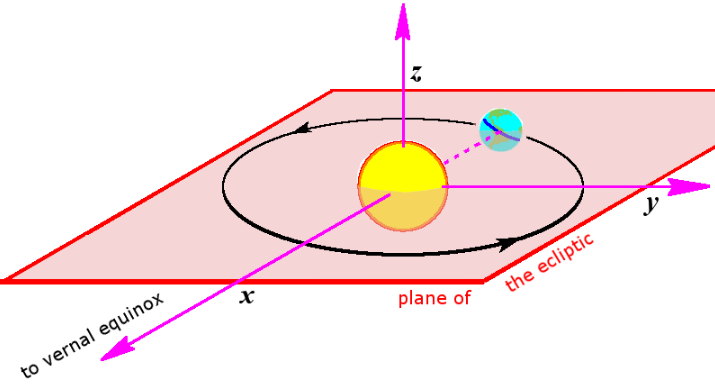

#### Mars-centered Ecliptic

Identical to Earth-centered Ecliptic, but the origin is at the center of Mars rather than Earth.

#### Earth-centered Equatorial

This coordinate system is fixed relative to the background stars.

Positive x: Same as Earth-centered Ecliptic

Positive z: Points towards the north pole

Positive y: Completes right handed triad.

#### Earth-fixed Equatorial

This coordinate system is fixed relative to the Earth's surface and rotates with it.

Positive x: Points in the direction of the Prime Meridian (0 degrees longitude)

Positive z: Points towards the north pole

Positive y: Completes right handed triad.

### Keplerian Orbital Elements

Used to define the size, shape, and orinetation of an orbit

- h - specific angular momentum

- i - inclination

- $\Omega$ - right ascension of the ascending node

- e - eccentricity

- $\omega$ - argument of perigee

- $\upsilon$ - true anomaly

Note that specific angular momentum is found by dividing the angular mometum of an obiting object by its mass. The elements for the orientation of the orbit are visualized in the diagram below.

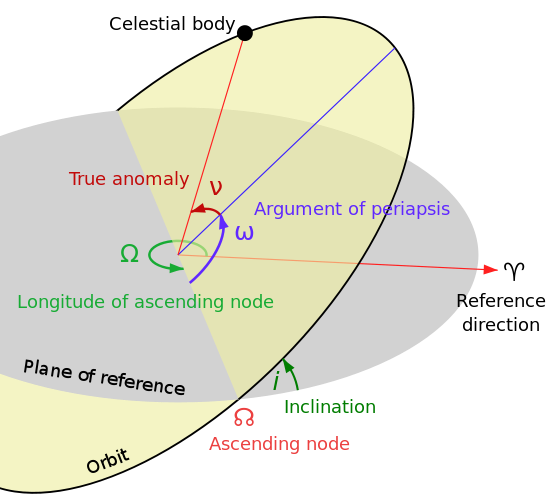

Note that the reference direction is often defined to be the positive x axis of the coordinate system in use.

## Mission Phases

### Transfers Between Earth and Mars

#### Introduction

An interplanetary trajectory is a heliocentric orbit that takes a spacecraft from one planet to another. For this project, the transfers from Earth to Mars and vice versa need to be calculated. Although neither of these steps is first chronologically, it makes sense to start with them since the launch to Earth orbit requires the information about the Earth to Mars transfer.

#### Simplifying Assumptions

Assume Earth and Mars follow circular orbits around the Sun at their mean orbital radii and that their orbits lie in the same plane. Given the sizes of Earth and Mars relative to their orbits, this assumption would lead to large errors in real life. However, its results can still be used for mission planning purpouses. Additionally, this section doesn't model the gravitational effect of any bodies other than the Sun since they are negligible for almost all of the transfer.

#### Problem Statement

Given the initial angles of Earth and Mars relative to the vernal equinox, find the impluse manuvers in the Solar-centered Ecliptic coordinate system required to transfer from one planet to the other. Fuel usage should be minimized, and as such, the spacecraft can wait at the planet of origin unitl its transfer window arrives.

#### Solution

Constants and initial conditions are set in the Hohmann_setup.m script. It calls the hohmann_transfer.m function to compute the first transfer, finds the new angles of the planets after the first transfer, and runs hohmann_transfer.m again for the return trip.

run("Hohmann_setup.m")

#### Verification

To make sure that the spacecraft stays at Earth before the start of the burn and reaches Mars by the end of the transfer, run the simulation Hohmann_outbound_sim.slx.

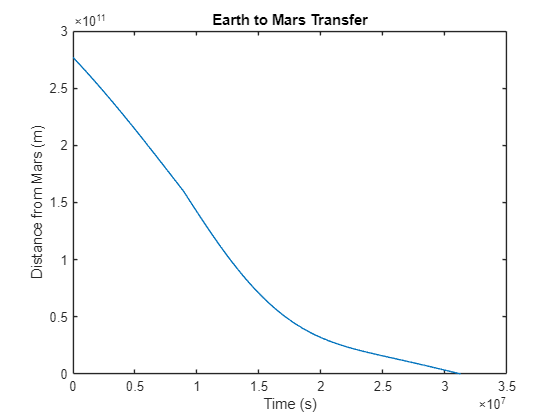

simOut = sim("Hohmann_outbound_sim.slx", 'ReturnWorkspaceOutputs', 'on');

plot_signal(simOut,"mars_dist","Distance from Mars (m)","Earth to Mars Transfer")

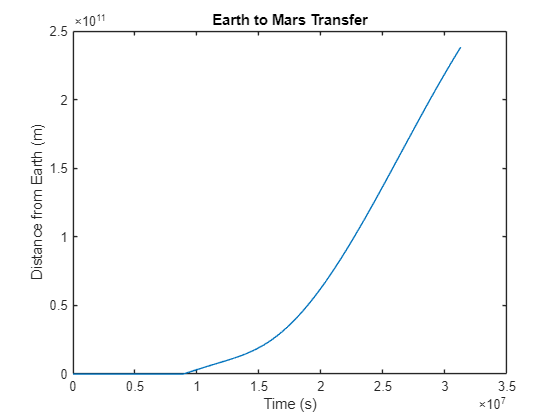

plot_signal(simOut,"earth_dist","Distance from Earth (m)","Earth to Mars Transfer")

The return trip can also be verified with a nearly identical simulation: Hohmann_inbound_sim.slx. Note that t=0 for this new simulation is the end of the previous simulation.

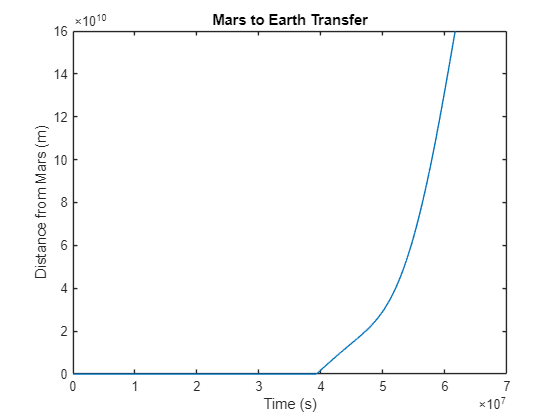

simOut = sim("Hohmann_inbound_sim.slx", 'ReturnWorkspaceOutputs', 'on');

plot_signal(simOut,"mars_dist","Distance from Mars (m)","Mars to Earth Transfer")

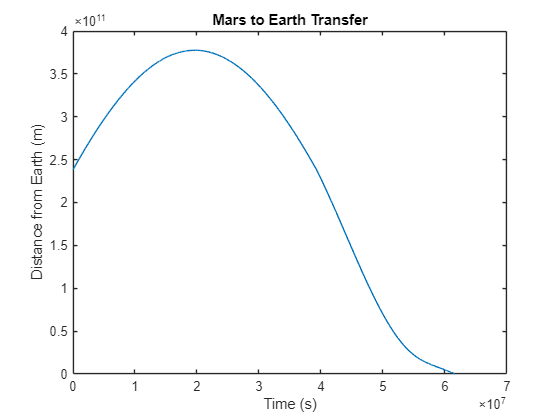

plot_signal(simOut,"earth_dist","Distance from Earth (m)","Mars to Earth Transfer")

## Launch to and Escape from Earth Orbit

#### Introduction

Now that the transfer from Earth to Mars has been calculated, we can go back to the beginning of the mission and calculate the manuvers required to get a spacecarft from the launch site, into Earth orbit, and onto and escape trajectory for Mars.

#### Simplifying Assumptions

Since rocket launches are very complex situations that bring up many problems that don't directly relate to orbital mechanics, this project assumes the spacecraft is sitting on a platform at the desired orbital altitude that rotates with the Earth. In this case, "launching" to orbit means applying an impulse manuver at the right time and direction to immedatly end up in the target orbit.

#### Problem Statement

Given a launch site's latitude and longitude coordinates, calculate the impluse manuver in the Earth-centered Equatorial coordinates required to put the orbiter into a circular parking orbit. This parking orbit should be in the plane of the ecliptic (i.e. incliation = 0 when using Earth-centered Ecliptic coordinates) to match with the calculations done for the Earth to Mars transfer. Then calculate the escape manuver in the Earth-centered Equatorial coordinates required to put the spacecraft onto that transfer.

#### Solution

Constants and initial conditions are set in the Earth_setup.m script. It calls the launch2orbit.m function to compute the launch manuver and uses this data to call the escape.m funciton to find the escape manuver.

run("Earth_setup.m")

#### Verification

Both of the manuvers in this section are simulated by the Earth_sim.slx simulation.

While the orbiter is sitting on its platform at orbital height, its eccentricity is near one. This is because its velocity is only due to the rotation of Earth before the launch. Additionally, the inclinanation will change as the plane of the "orbit" moves due to the Earth's rotation. 

After the launch manuver, the eccentricity and ecliptic eccentricity should be near zero if its in a circular orbit in the plane of the ecliptic. 

Finally, once the orbiter performs the escape manuver, the eccentricity should be greater than 1 (it should be a hyperbolic escape orbit), the ecliptic eccentricity should stay near zero, the cosine of the angle between the actual and target escape velocities should be near 1, and the difference in magnitudes between these velocities should go to zero as time goes to infinity. Note that the velocity difference goes to zero very slowly. Running the simulation for longer shows better convergence to zero.

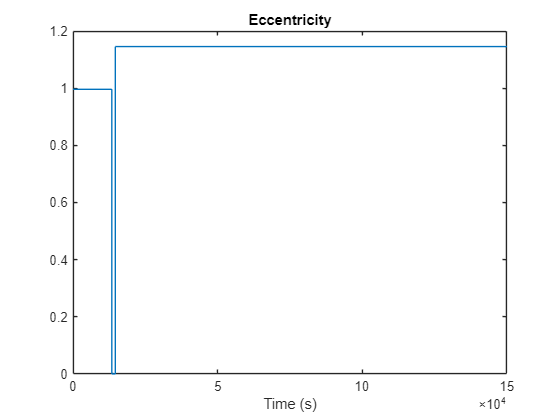

simOut = sim("Earth_sim.slx", 'ReturnWorkspaceOutputs', 'on');

plot_signal(simOut,"<e>","","Eccentricity")

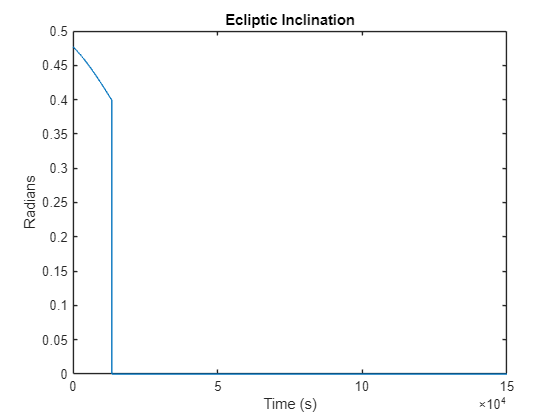

plot_signal(simOut,"<i>","Radians","Ecliptic Inclination")

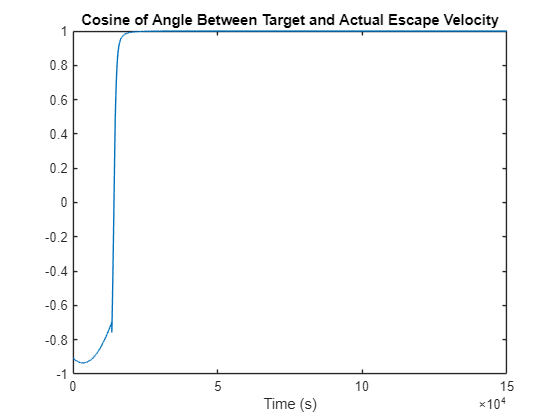

plot_signal(simOut,"cos_theta","","Cosine of Angle Between Target and Actual Escape Velocity")

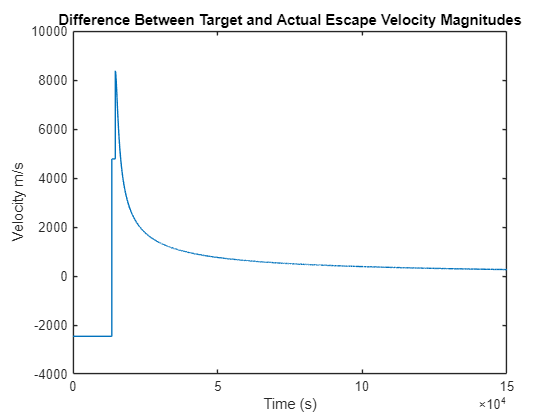

plot_signal(simOut,"vel_mag_diff","Velocity m/s","Difference Between Target and Actual Escape Velocity Magnitudes")

## Mars Capture

#### Introduction

Now that the manuvers around Earth and the interplanetry transfers around Mars have been calcualted, it's time to find the manuver that puts the orbiter into orbit around Mars rather than flying past it. Not only that, but we need to make sure that the orbiter is put into the right plane to rendevous with the sample canister waiting in Mars orbit. 

#### Simplifying Assumptions

Mars' gravity only begins to effect the orbiter once it gets within one million km. Also, assume that the canister is waiting in a circular orbit. Lastly, it can be assumed that the orbiter begins on the assymtote formed by its hyperbolic trajectory with velocity equal to its velocity at infinity. This will lead to small errors since the orbiter's velocity at infinity is slightly different than its velocity at one million km.

#### Problem Statement

The orbiter will approach Mars with some inital velocity relative to the planet found in the interplanetry transfer step. The line passing though the center of Mars that is parallel to the aformentioned velocity vector will be refered to as the line of approach. The initial distance from the line of approach will determine the periapsis and should be caluclated to match that of the sample canister. This gives a circle of possible starting points for the orbiter at a given distance from Mars. The goal will be to choose the correct starting point along this circle such that the orbiter is in the plane of the sample cansiter. In reality, the exact position of the spacecraft would be determined by the specifics of the interplanetary transfer, but for the purpouses of this project, it's much easier to assume that it can be choosen at will along this predefined circle. Also, note that the orbiter's RA is fixed by the approach direction, meaning that the sample canister will have to be launched into a certian RA to meet the orbiter. Lastly, the orbiter will need to calculate the manuver required to capture it into a circular Mars orbit given the inital conditions described above.

#### Solution

Constants and initial conditions are set in the Mars_capture_setup.m script. It calls the capture.m function to compute the all the initial conditions and the Mars capture manuver.

run("Mars_capture_setup.m")

#### Verification

This section is verified by the Mars_capture_sim.slx simulation.

First of all, we need to make sure that the orbiter stays in the plane of the sample canister. This can be checked by looking at the difference in normal vectors of both planes. Of course, if they're in the same plane, it should be very near zero.

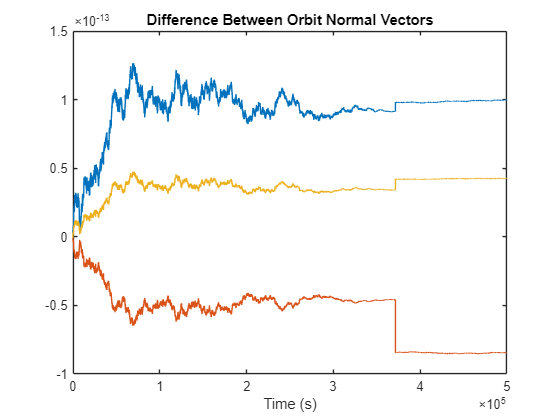

simOut = sim("Mars_capture_sim.slx", 'ReturnWorkspaceOutputs', 'on');

plot_signal(simOut,"plane_diff","","Difference Between Orbit Normal Vectors")

Additionally, we need to make sure that the orbiter's capture manuver puts it into a ciruclar orbit around Mars. This can be checked by looking at the eccentricity. Before the capture it should be above one and after the capture it should be near zero.

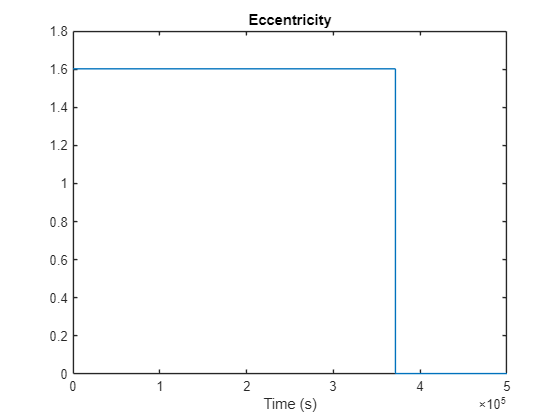

plot_signal(simOut,"<e>","","Eccentricity")

Finally, check that the periapsis radius is nearly constant thorughout the simulation and that it is close to the canister alititude of 3746 km.

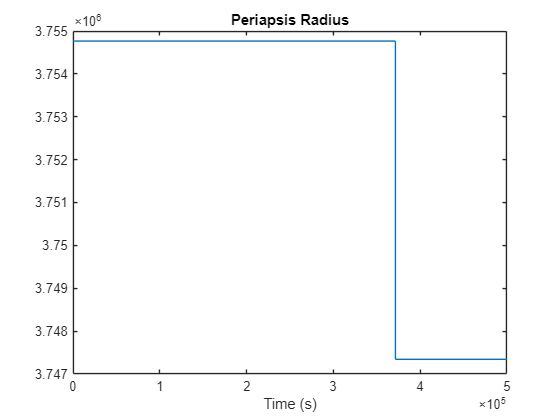

plot_signal(simOut,"<r_p>","","Periapsis Radius")

## Sample Canister Rendevous

#### Introduction

Now that both the orbiter and the sample canister are in very similar orbits around Mars, its time to calculate the rendevous manuver that brings the two spacecraft into close proximity with zero relative velocity.

#### Simplifying Assumptions

Assume that both spacecraft are already relativly close prioir to the start of the rendevous manuvers. This allows the relative dynamics of the spacecraft to be modeled with the linearized Clohessy–Wiltshire equations.

#### Problem Statement

Given the initial orbital elements of the two spacecraft, find the two impluse rendezvous manuver in Mars-centered Ecliptic coordinates. Note that in theory this problem can be solved for any rendezvous time, but in practice it works better for shorter rendezvous times. That said, shorter transfer times require more delta-V to perform. Therefore, this trade-off should be taken into consideration when choosing a rendezvous time.

#### Solution

Constants and initial conditions are set in the Rendezvous_setup.m script. It calls the rendezvous.m function to compute the rendezvous manuvers.

run("Rendezvous_setup.m")

#### Verification

This section is verified by the Rendezvous_sim.slx simulation.

First of all, we need to make sure the orbiter reaches the canister. This can be checked by plotting the relative distance between the two over time.

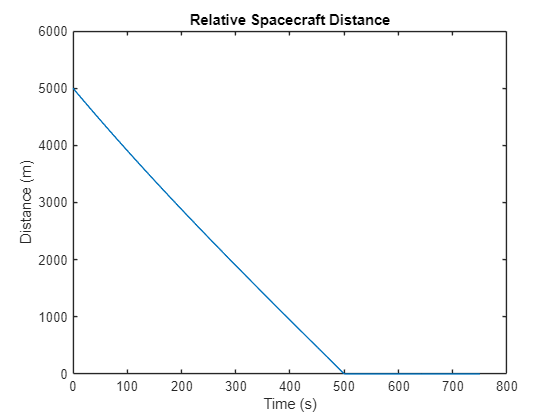

simOut = sim("Rendezvous_sim.slx", 'ReturnWorkspaceOutputs', 'on');

plot_signal(simOut,"rel_dist","Distance (m)","Relative Spacecraft Distance")

Additionally, we need to make sure that the relative velocity between the two is negligible after both manuvers are completed.

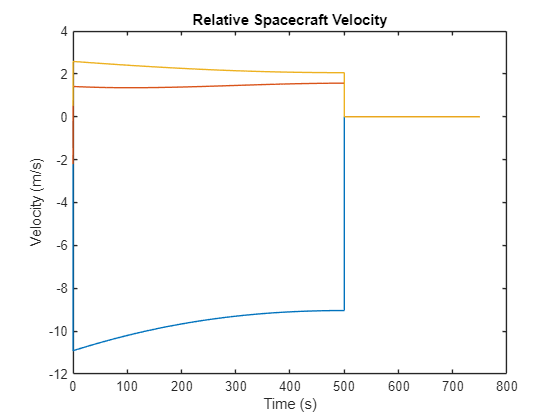

plot_signal(simOut,"rel_vel","Velocity (m/s)","Relative Spacecraft Velocity")

## Mars Escape

#### Introduction

Now that the orbiter has rendezvoued with the sample canister, it's time to perform the escape burn that will put both of them onto the interplanetary trajectory towards Earth.

#### Problem Statement

Given the initial orbital elements of the orbiter, find the manuver in Mars-centered Ecliptic coordinates required to put it on the Mars to Earth transfer calculated earlier.

#### Solution

Constants and initial conditions are set in the Mars_escape_setup.m script. It calls the escape.m function to compute the escape manuver.

run("Mars_escape_setup.m")

#### Verification

This section is verified by the Mars_escape_sim.slx simulation.

Once the orbiter performs the escape manuver, the cosine of the angle between the actual and target escape velocities should be near 1, and the difference in magnitudes between these velocities should go to zero as time goes to infinity. Note that the velocity difference goes to zero very slowly. Running the simulation for longer shows better convergence to zero.

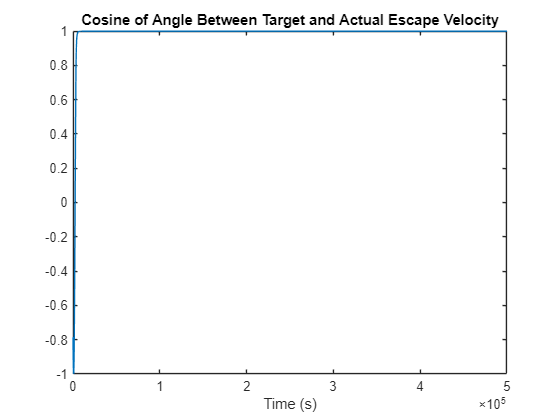

simOut = sim("Simulations/Mars_escape_sim.slx", 'ReturnWorkspaceOutputs', 'on');

plot_signal(simOut,"cos_theta","","Cosine of Angle Between Target and Actual Escape Velocity")

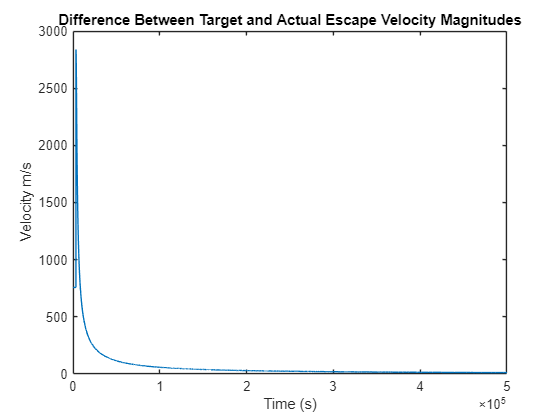

plot_signal(simOut,"vel_mag_diff","Velocity m/s","Difference Between Target and Actual Escape Velocity Magnitudes")